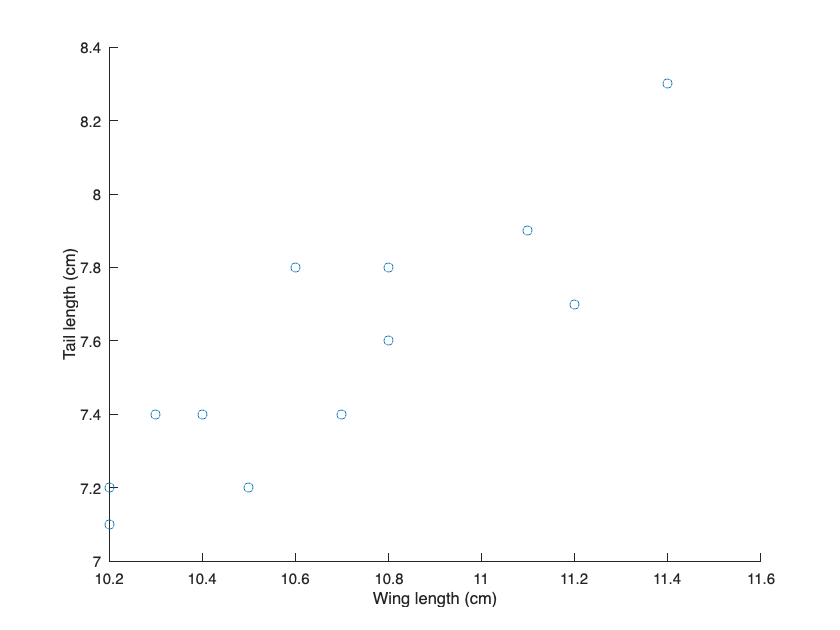

%Assume Wing length is the  variable and Tail Length is the  variable, both measured in cm.
%Plot X vs Y. Do they look related?
wing_vs_tail_length= [10.4	7.4
10.8	7.6
11.1	7.9
10.2	7.2
10.3	7.4
10.2	7.1
10.7	7.4
10.5	7.2
10.8	7.8
11.2	7.7
10.6	7.8
11.4	8.3];
scatter(wing_vs_tail_length(:, 1), wing_vs_tail_length(:, 2));
xlabel('Wing length (cm)')
ylabel('Tail length (cm)')

- There appears to be a positive correlation between wing and tail length

%Calculate rXY and rYX first using the equations above and then using Matlab's built-in corrcoef. 
% Did you get the same answers?
X= wing_vs_tail_length(:, 1);
Y= wing_vs_tail_length(:, 2);
X_bar= mean(X);
Y_bar= mean(Y);
for i= 1:length(X); %calculate components of rXY
    numerator(i, 1)= (X(i)-X_bar)*(Y(i)-Y_bar);
    x_denominator(i, 1)= (X(i)-X_bar)^2;
    y_denominator(i, 1)= (Y(i)-Y_bar)^2;
end
rXY= sum(numerator)/(sqrt(sum(x_denominator))*sqrt(sum(y_denominator)));
%What is the difference between rXY and rYX?
%Using MATLAB built in function
rXY_2= corrcoef(X, Y); %rXY as found by built in function

        2. I got the same answers with the MATLAB function as I did using the equation.

%What is the standard error of rXY?
n= length(X);
s_r= sqrt((1-rXY^2)/(n-2)); %standard error of rXY

%What is the 95% confidence intervals computed from the standard error?

%Take the Fisher's z-transformation of r
z= 0.5*log((1+rXY)/(1-rXY));

%Compute its standard deviation
s_z= sqrt(1/(n-3));

%Compute confidence intervals in this z-space
z_crit= norminv(0.95);
CI_pos= (z+z_crit)*s_z;
CI_neg= (z-z_crit)*s_z;

%Translate each z-value back to r
CI_r1= (exp(2*CI_pos)-1)/(exp(2*CI_pos-1));
CI_r2= (exp(2*CI_neg)-1)/(exp(2*CI_neg-1));
confidence_intervals= [CI_r1, CI_r2];


%Should the value of rXY be considered significant at the p<0.05 level, 
% given a two-tailed test (i.e., we reject if the test statistic is too large 
% on either tail of the null distribution) for H0:rXY= 0?
t= rXY/s_r; %find t-value

t_cumdist= tcdf(t, n-2);
p_val= 1-t_cumdist;
if p_val< 0.05;
    disp('rXY is significant')
end

rXY is significant


rs= 0.75;
z_rs= 0.5*log((1+rs)/(1-rs));
lambda= (z-z_rs)/sqrt(1/(n-3));
t_cumdist= tcdf(lambda, n-2);
p_val= 1-t_cumdist;
if p_val< 0.05;
    disp('rXY is significant')
else
    disp('rXY is not the same as Yales value')
end

rXY is not the same as Yales value


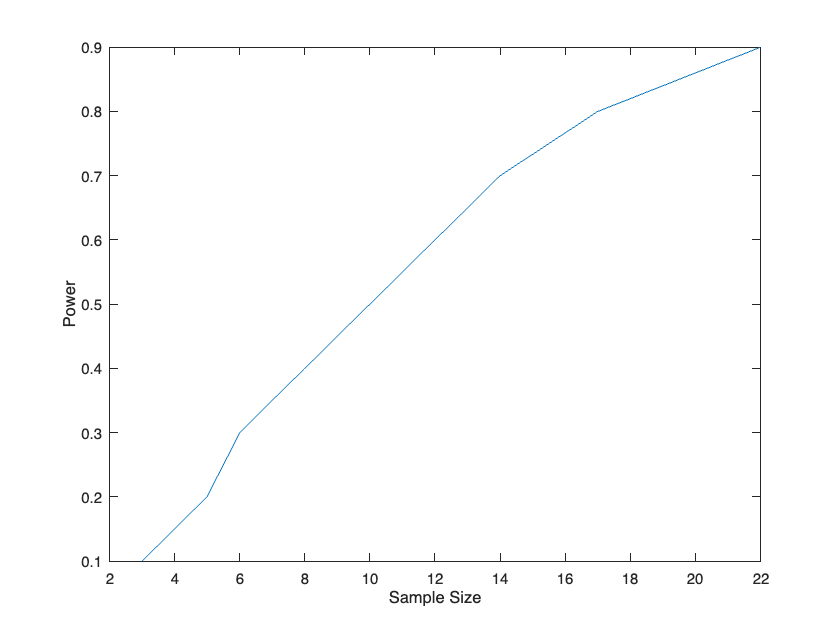

%
powers= [0.1:0.1:0.9];
for i=1:length(powers)
    samplesize(i)= sampsizepwr("t", [0 0.68], 0.5, powers(i));
end
plot(samplesize, powers);
xlabel("Sample Size");
ylabel("Power");